% load test data 
load('data_25_jul_2022_test_with_0_01_ref.mat')

## load model results


%load('D:\work\phd\dl_project\sol_refactored\AICavity\test_pred\conv_and_fully_connected_fourier_pred_on_test.mat')
%load('D:\work\phd\dl_project\sol_refactored\AICavity\test_pred\conv_and_fully_connected_pred_on_test.mat')
%load('D:\work\phd\dl_project\sol_refactored\AICavity\test_pred\fully_connected_fourier_pred_on_test.mat')
%load('D:\work\phd\dl_project\sol_refactored\AICavity\test_pred\fully_connected_pred_on_test.mat')
%load('D:\work\phd\dl_project\sol_refactored\AICavity\test_pred\fully_convolutional_fourier_pred_on_test.mat')
%load('D:\work\phd\dl_project\sol_refactored\AICavity\test_pred\fully_convolutional_pred_on_test.mat')
%load('D:\work\phd\dl_project\sol_refactored\AICavity\test_pred\conv_and_fully_connected_fourier_concat_pred_on_test.mat')
load('D:\work\phd\dl_project\sol_refactored\AICavity\test_pred\fully_convolutional_fourier_concat_pred_on_test.mat')
det_inds = ((prediction>0.5 ).*double(labels'));
labels = labels';

% Stats
nt = sum(labels);
tot_el = numel(labels);
tn_f =  @(t)(sum((prediction<=t ).*double(labels==0)));
fn_f =  @(t)(sum((prediction>t ).*double(labels==0)));
fp_f =  @(t)(sum((prediction<=t ).*double(labels==1)));
tp_f =  @(t)(sum((prediction>t ).*double(labels==1)));

accuracy_f = @(t)((sum((prediction<=t ).*double(labels==0))/(tot_el-nt)+sum((prediction>t ).*double(labels))/nt)/2);
presicion = tp_f(0.5)/(tp_f(0.5)+fp_f(0.5))

presicion = 0.8409

recall = tp_f(0.5)/(tp_f(0.5)+fn_f(0.5))

recall = 0.9140

accuracy = accuracy_f(0.5)

accuracy = 0.8816

f1= 2*presicion*recall/(presicion+recall)

f1 = 0.8759

ac = auc(prediction,labels)

ac = 0.8632

ac

ac = 0.8632

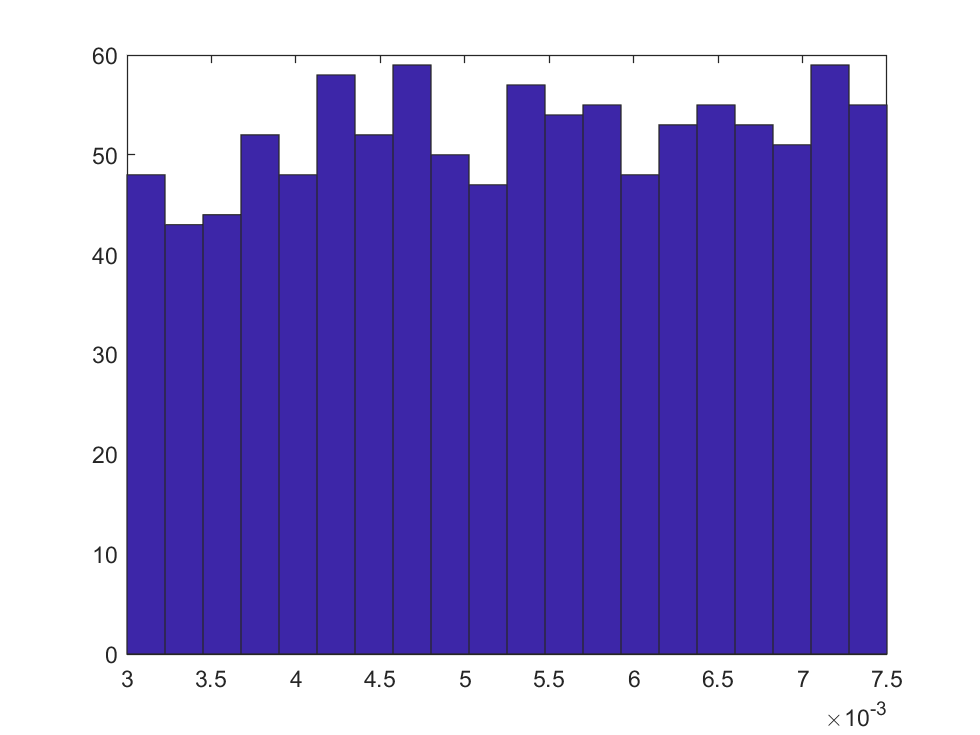


%% By Radius
nbins = 20;

det_holes_rad = hole_rad_vec(det_inds==1);

figure,hist(det_holes_rad,nbins )

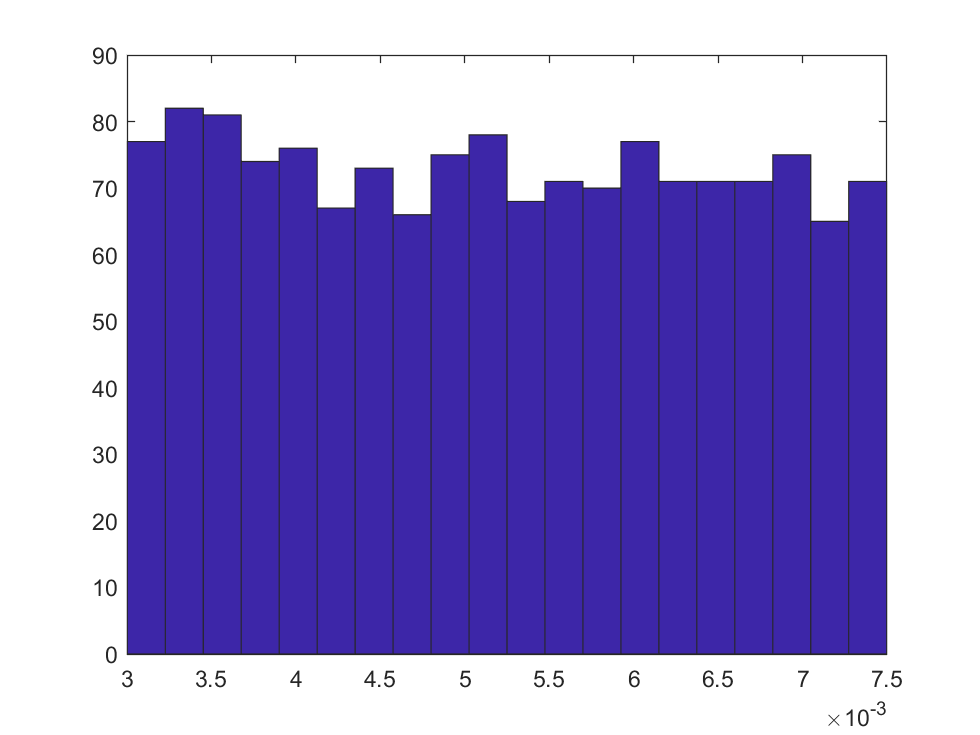

det_holes_rad_miss = hole_rad_vec(det_inds==0);
figure,hist(det_holes_rad_miss,nbins )

## By dist

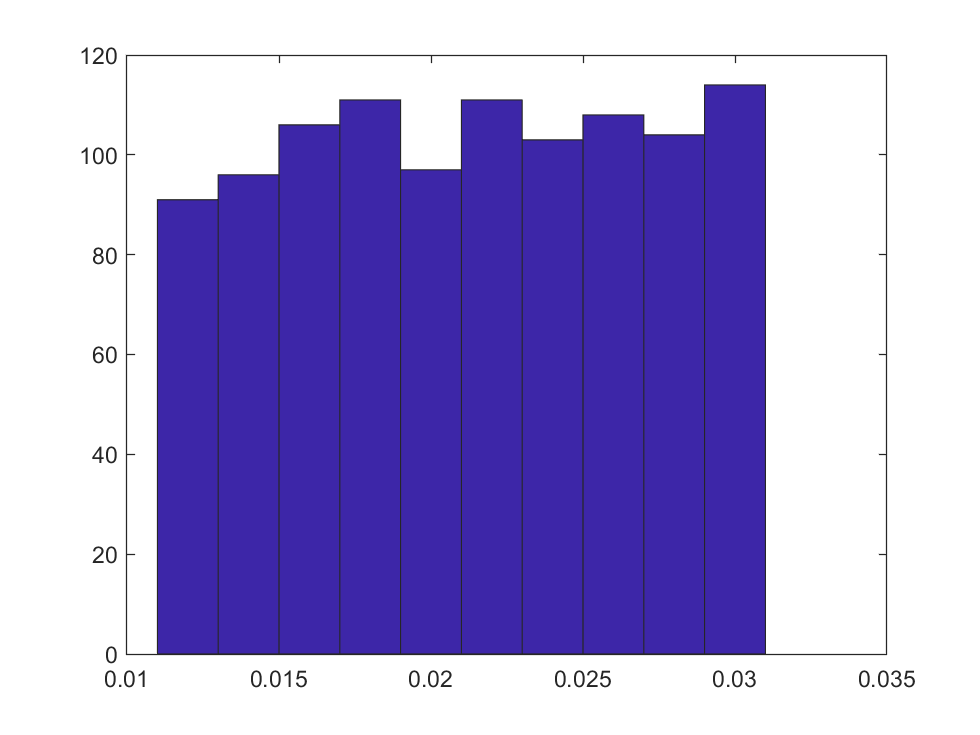

det_holes_dist = sur_dist_vec(det_inds==1);

figure,hist(det_holes_dist,10)

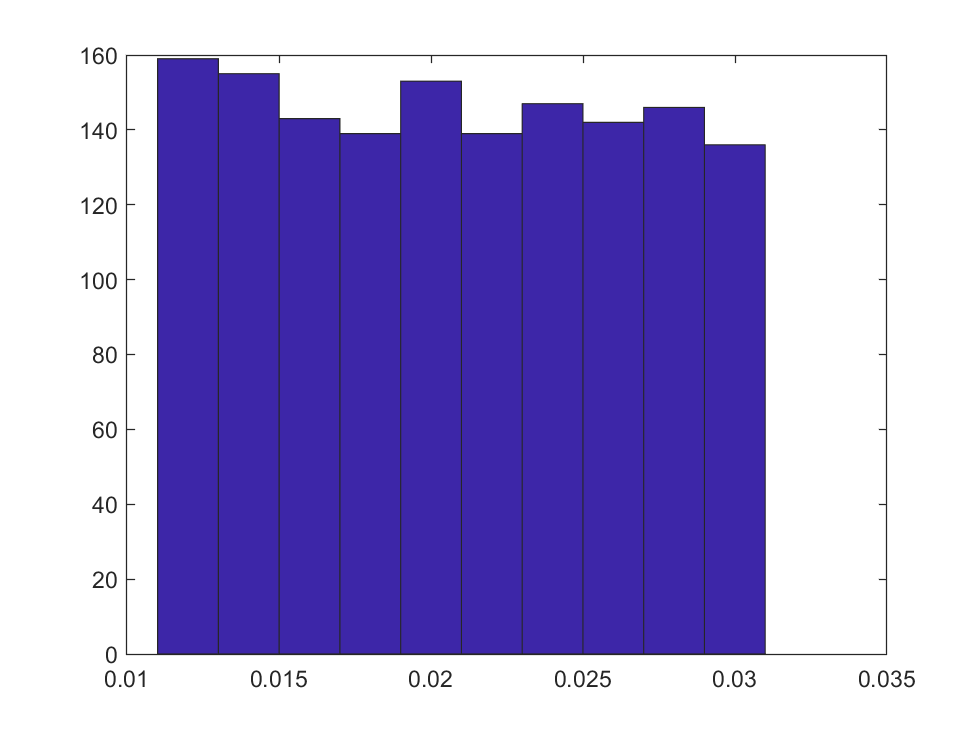

det_holes_dist_miss = sur_dist_vec(det_inds==0);
figure,hist(det_holes_dist_miss,10)

## By tilt

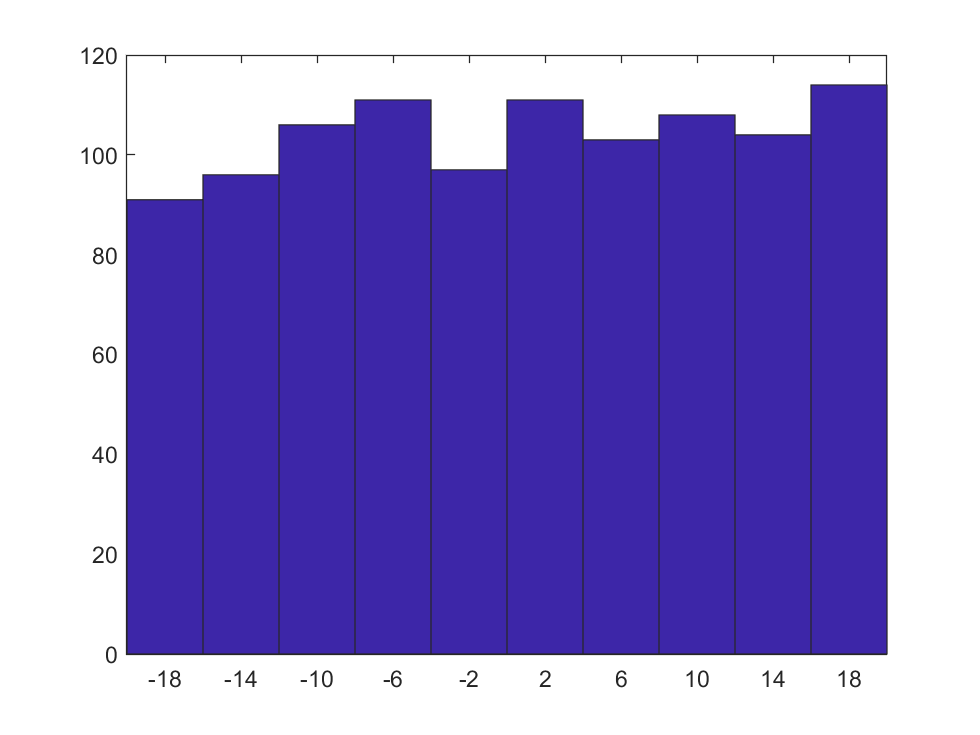

det_holes_tilt = sur_tilt_vec(det_inds==1);

figure,hist(det_holes_tilt,10)

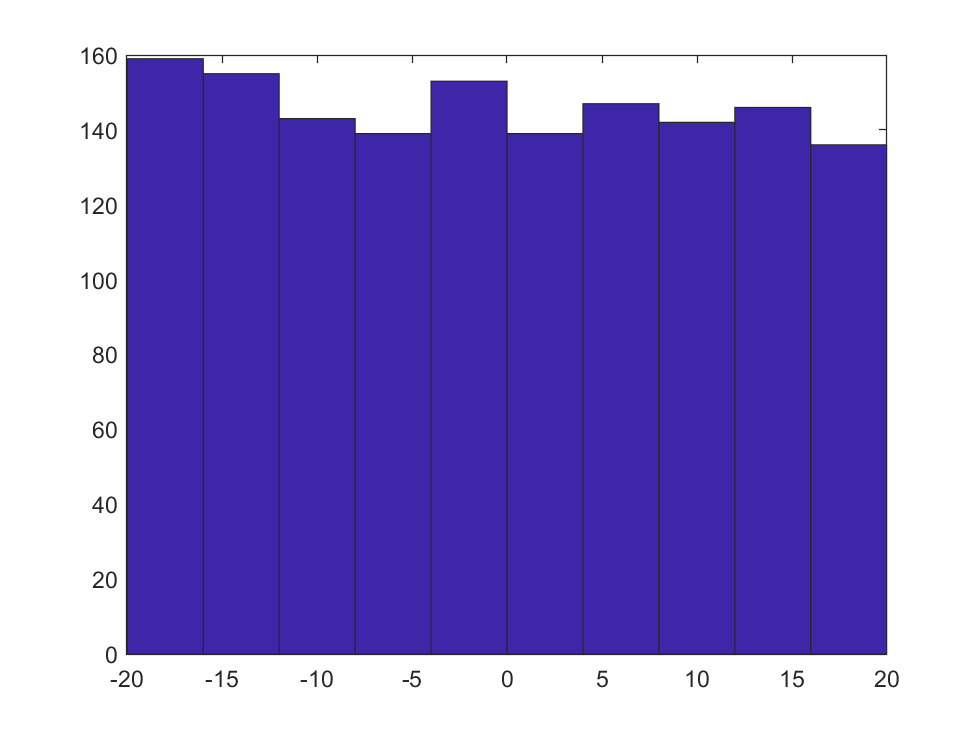

det_holes_tilt_miss = sur_tilt_vec(det_inds==0);
figure,hist(det_holes_tilt_miss,10)